osf = 10

osf = 10

cmap =          0         0         0
    0.0039    0.0039    0.0039
    0.0078    0.0078    0.0078
    0.0118    0.0118    0.0118
    0.0157    0.0157    0.0157
    0.0196    0.0196    0.0196
    0.0235    0.0235    0.0235
    0.0275    0.0275    0.0275
    0.0314    0.0314    0.0314
    0.0353    0.0353    0.0353


a =      8    18    28    38    48    58    68
     8    18    28    38    48    58    68
     8    18    28    38    48    58    68
     8    18    28    38    48    58    68
     8    18    28    38    48    58    68
     8    18    28    38    48    58    68
     8    18    28    38    48    58    68


b =      8     8     8     8     8     8     8
    18    18    18    18    18    18    18
    28    28    28    28    28    28    28
    38    38    38    38    38    38    38
    48    48    48    48    48    48    48
    58    58    58    58    58    58    58
    68    68    68    68    68    68    68


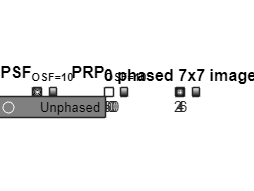

[psf, x, y] = diffraction_psf(1e-6, 20, 5e-7);
prp = conv2(psf/sum(psf(:)),ones(osf),'same');
%prp = padarray(prp,[10,10]);
sam = round(size(prp,1)/2)+[-3:3]*osf;
im = prp(sam,sam);

%static prp
if 1
    figure
cmap = gray(256)
subplot(1,3,1)
imagesc(psf); axis equal; axis tight
colorbar; set(gca,"ColorScale","log")
title("PSF_{OSF=10}")
subplot(1,3,2)
imagesc(prp); axis equal; axis tight; hold on
colorbar; set(gca,"ColorScale","log")
title("PRP_{OSF=10}")
[a,b]=meshgrid(sam)
scatter(a(:),b(:),'w')
lh = legend({'Unphased','Phased'}); set( lh, 'Box', 'on', 'Color',[.5 .5 .5] )
subplot(1,3,3)
imagesc(im); axis equal; axis tight
colorbar; set(gca,"ColorScale","log")
title("0 phased 7x7 image")
colormap(cmap)
end

a =      8    18    28    38    48    58    68
     8    18    28    38    48    58    68
     8    18    28    38    48    58    68
     8    18    28    38    48    58    68
     8    18    28    38    48    58    68
     8    18    28    38    48    58    68
     8    18    28    38    48    58    68


b =      8     8     8     8     8     8     8
    18    18    18    18    18    18    18
    28    28    28    28    28    28    28
    38    38    38    38    38    38    38
    48    48    48    48    48    48    48
    58    58    58    58    58    58    58
    68    68    68    68    68    68    68


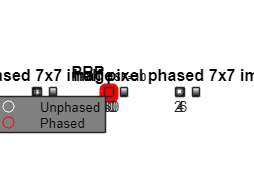


%phasing
if 1
    figure
subplot(1,3,1)
imagesc(prp(sam,sam)); axis equal; axis tight
colorbar; set(gca,"ColorScale","log")
title("0 phased 7x7 image")
colormap(cmap)
subplot(1,3,2)
imagesc(prp); axis equal; axis tight; hold on
colorbar; set(gca,"ColorScale","log")
title("PRP_{OSF=10}")
[a,b]=meshgrid(sam)
scatter(a(:),b(:),'w')
scatter(a(:)+5,b(:)+5,'r')
lh = legend({'Unphased','Phased'}); set( lh, 'Box', 'on', 'Color',[.5 .5 .5] )
subplot(1,3,3)
imagesc(prp(sam+5,sam+5)); axis equal; axis tight
colorbar; set(gca,"ColorScale","log")
title("half pixel phased 7x7 image")
colormap(cmap)
end


%Linear
prp = padarray(prp,[10,10]);
sam = round(size(prp,1)/2)+[-3:3]*osf;
mot = 10

mot = 10

jitt = 10;
lin = [-mot:mot]

lin =    -10    -9    -8    -7    -6    -5    -4    -3    -2    -1     0     1     2     3     4     5     6     7     8     9    10


for i = 1:length(sam)
    for j = 1:length(sam)
        imM(i,j) = mean(prp(sub2ind(size(prp),sam(i)+lin,sam(j)+lin)),'all');
    end
end
figure
subplot(1,2,1)
imagesc(prp); axis equal; axis tight; hold on
c = jet(length(lin)); a = 0

a = 0

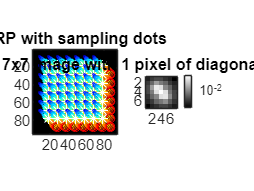

for i = 1:length(sam)
    for j = 1:length(sam)
        scatter(sam(i)+lin,sam(j)+lin,[1:length(lin)],c); hold on
        scatter(sam(i),sam(j),'w*')
    end
end
title('PRP with sampling dots')
subplot(1,2,2)
imagesc(imM); axis equal; axis tight
colorbar; set(gca,"ColorScale","log")
title("7x7 Image with 1 pixel of diagonal motion")
colormap(cmap)


%Linear + jitter
jitX = round(normrnd(lin,jitt))

jitX =     -9    -1    -6     8     0    -1     5     2    -1   -25    -3    -6    22     0     3   -14     5    24    -2    11    11


jitY = round(normrnd(lin,jitt))

jitY =      2    -4     2   -11     8     2   -20     0    14    -2    -4    -7   -12     7    12    -6    12    -3     4    14    26


for i = 1:length(sam)
    for j = 1:length(sam)
        sam1 = sam(i)+jitX; sam1(sam1<1) =1; sam1(sam1>size(prp,1)) = size(prp,1);
        sam2 = sam(j)+jitY; sam2(sam2<1) =1; sam2(sam2>size(prp,1)) = size(prp,1);
        imJ(i,j) = mean(prp(sub2ind(size(prp),sam1,sam2)),'all');
    end
end
figure
subplot(1,2,1)
imagesc(prp); axis equal; axis tight; hold on;
a = 0

a = 0

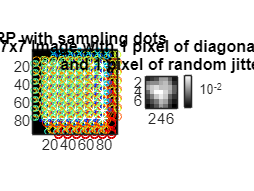

for i = 1:length(sam)
    for j = 1:length(sam)
        sam1 = sam(i)+jitX; sam1(sam1<1) =1; sam1(sam1>size(prp,1)) = size(prp,1);
        sam2 = sam(j)+jitY; sam2(sam2<1) =1; sam2(sam2>size(prp,1)) = size(prp,1);
        scatter(sam1,sam2,[1:length(jitY)],c); hold on
        scatter(sam(i),sam(j),'w*')
    end
end
title('PRP with sampling dots')
subplot(1,2,2)
imagesc(imJ); axis equal; axis tight
colorbar; set(gca,"ColorScale","log")
title(sprintf("7x7 Image with 1 pixel of diagonal motion \n and 1 pixel of random jitter"))
colormap(cmap)




%Linear + jitter super sampled
lin = linspace(-mot,mot,100)

lin =   -10.0000   -9.7980   -9.5960   -9.3939   -9.1919   -8.9899   -8.7879   -8.5859   -8.3838   -8.1818   -7.9798   -7.7778   -7.5758   -7.3737   -7.1717   -6.9697   -6.7677   -6.5657   -6.3636   -6.1616   -5.9596   -5.7576   -5.5556   -5.3535   -5.1515   -4.9495   -4.7475   -4.5455   -4.3434   -4.1414   -3.9394   -3.7374   -3.5354   -3.3333   -3.1313   -2.9293   -2.7273   -2.5253   -2.3232   -2.1212   -1.9192   -1.7172   -1.5152   -1.3131   -1.1111   -0.9091   -0.7071   -0.5051   -0.3030   -0.1010


jitX = round(normrnd(lin,jitt))

jitX =      3    -5   -26   -11   -30    -4   -11   -13   -19   -12     1   -17     6   -13   -13    -7   -18    10   -26   -10   -14    -6    -5     0    15    -2    -3    -5    -5   -21    19    -4     4    -1    -3   -10     8    21    -5    -4     9    -7    17   -13    18     9     1    11   -10   -20


jitY = round(normrnd(lin,jitt))

jitY =    -31   -20   -16     1   -17    -3     6   -26   -32   -10   -16    -8   -11    -7     3    -3     1     4   -21   -11     1    -8    -5   -22   -23    11     4    19   -12     4     4    14    -3    -1    -7    -2    -3    -5   -25    -7     0   -11    11     1    -4   -22   -17    23    -5    20


for i = 1:length(sam)
    for j = 1:length(sam)
        sam1 = sam(i)+jitX; sam1(sam1<1) =1; sam1(sam1>size(prp,1)) = size(prp,1);
        sam2 = sam(j)+jitY; sam2(sam2<1) =1; sam2(sam2>size(prp,1)) = size(prp,1);
        imJ(i,j) = mean(prp(sub2ind(size(prp),sam1,sam2)),'all');
    end
end
figure
subplot(1,2,1)
imagesc(prp); axis equal; axis tight; hold on;
c = jet(length(lin)); a = 0

a = 0

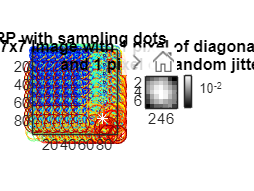

for i = 1:length(sam)
    for j = 1:length(sam)
        sam1 = sam(i)+jitX; sam1(sam1<1) =1; sam1(sam1>size(prp,1)) = size(prp,1);
        sam2 = sam(j)+jitY; sam2(sam2<1) =1; sam2(sam2>size(prp,1)) = size(prp,1);
        scatter(sam1,sam2,[1:length(jitY)],c); hold on
        scatter(sam(i),sam(j),'w*')
    end
end
title('PRP with sampling dots')
subplot(1,2,2)
imagesc(imJ); axis equal; axis tight
colorbar; set(gca,"ColorScale","log")
title(sprintf("7x7 Image with 1 pixel of diagonal motion \n and 1 pixel of random jitter"))
colormap(cmap)




% Generate a psf
function [psf, x, y] = diffraction_psf(pixel_pitch, f_number, wavelength)
    % Generates the diffraction-limited point spread function (PSF).
    
    % Input arguments:
    %   pixel_pitch: Pixel pitch in meters.
    %   f_number: f-number of the optical system.
    %   wavelength (optional): Wavelength of light in meters. Defaults to 550nm.
    
    % Output arguments:
    %   psf: The PSF array.
    %   x: The x-coordinates of the PSF grid.
    %   y: The y-coordinates of the PSF grid.
    
    if nargin < 3
        wavelength = 550e-9; % Default wavelength: green light
    end
    
    % Calculate the Airy disk radius (first minimum)
    airy_radius = 1.22 * wavelength * f_number;
    
    % Create a grid for the PSF
    psf_size = ceil(6 * airy_radius / pixel_pitch); % Size of the PSF array
    if mod(psf_size, 2) == 0  % Ensure psf_size is odd for centering
        psf_size = psf_size + 1;
    end
    
    x = linspace(-psf_size/2, psf_size/2, psf_size) * pixel_pitch;
    y = linspace(-psf_size/2, psf_size/2, psf_size) * pixel_pitch;
    [X, Y] = meshgrid(x, y);
    r = sqrt(X.^2 + Y.^2);
    
    % Calculate the PSF using the Airy disk formula
    psf = zeros(size(r));
    nonzero_r = r > 0;
    psf(nonzero_r) = (2 * besselj(1, pi * r(nonzero_r) / airy_radius) ./ (pi * r(nonzero_r) / airy_radius)).^2;
    psf(r == 0) = 1.0; % Central maximum
    
    % Normalize the PSF (integral should be 1)
    psf = psf / sum(psf(:));
end